UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

2024

# *Laboratory 7: Interpolation*

## Instructions:

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name **Lab7_name_lastname.zip. **

- Send the report and all created files in a rar or zip file with name **Lab7_name_lastname.rar **and subject **Analisis_Lab7_name.** 

- You are allowed to use internet, notes, and .m files that you have created before. 

## Purposes:

- To understand the interpolation and polynomial approximation methods.

- To apply the interpolation and polynomial approximation methods.

- To implement the Langrage and Newton polynomials in Matlab.

- To interpret the Taylor polynomial approximation.

## Guide functions:

You will be introduced to some functions that may be useful for the development of this laboratory. You **DO NOT **have to use them if you do not requier them. This is with the purpose of providing a guide for you to understand Matlab and start coding more eficciently.

**Note:** Remember to save your Matlab functions as '.m' files.

- **expand(P)**:  multiplies all parentheses in P, and simplifies inputs to functions such as `cos(x + y)` by applying standard identities.

- **exp(x): **[`Y`](https://la.mathworks.com/help/matlab/ref/double.exp.html?lang=en#bt9_gkt-1-Y) `= exp(`[`X`](https://la.mathworks.com/help/matlab/ref/double.exp.html?lang=en#bt9_gkt-1-X)`)` returns the exponential $e^x$ for each element in array `X`.

- **@(x): **A function handle is a MATLAB® data type that stores an association to a function. Indirectly calling a function enables you to invoke the function regardless of where you call it from. In other words, calling local functions from outside the main function. Example:

`f(x) = @(x) x.^2;  -- Equals `$x^2$

`Ans = sqr(3)  -- Equals `${\left(3\right)}^2$

`Ans = 9`

## Practice

### *Implementing*

- **(0.5 points)** Create a Matlab function called my_LagrangePolynomial_name_lastname() to find the coefficients of the Lagrange interpolation polynomial P(x). Remember the formulas 

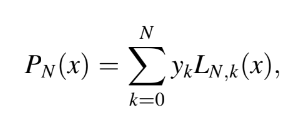 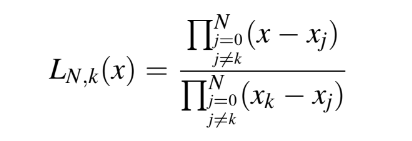

- The function arguments must be the set of points (X, Y) mentioned in the code box, finally evaluate the polynomial obtained at X=1.5.

X = [1, 1.25, 1.6];
Y = [0, (-(sqrt(2)/2)), -0.9510565163];

[P] = my_LagrangePolynomial_juan_jaimes(X, Y)

P = function_handle with value:
    @(x)P(x)+Y(i)*L_i(x)



Evaluacion_En_X1 = P(1.5)

Evaluacion_En_X1 = -0.9702

- **(0.5 points)** Using P(x) from the previous point, create a graph in the interval [0,3] and compare it with the graph of the function $\sin \left(\Pi *x\right)$ in the same plot.

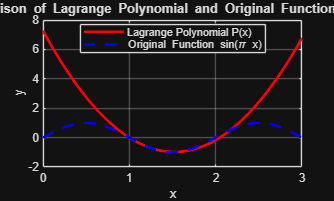

% Define the original function f(x) = sin(pi * x)
f = @(x) sin(pi * x);  % Original function
% Define the range for plotting
x_values = linspace(0, 3, 500);  % 500 points between 0 and 3

% Evaluate the Lagrange polynomial and the original function
y_P = arrayfun(P, x_values);  % Evaluate the polynomial at the points in x_values
y_f = f(x_values);  % Evaluate the original function at the points in x_values

% Plot the graphs
figure;
plot(x_values, y_P, 'r-', 'LineWidth', 2);  % Plot the Lagrange polynomial in red
hold on;
plot(x_values, y_f, 'b--', 'LineWidth', 2);  % Plot the original function in blue (dashed)
hold off;

% Add labels and legend
xlabel('x');
ylabel('y');
legend('Lagrange Polynomial P(x)', 'Original Function sin(\pi x)', 'Location', 'Best');
title('Comparison of Lagrange Polynomial and Original Function sin(\pi x)');
grid on;

- **(0.5 points)** Create a Matlab function called *my_NewtonPolynomial_name_lastname()* to find the coefficients of the Newton interpolating polynomial P1(X). Remember the formulas: 

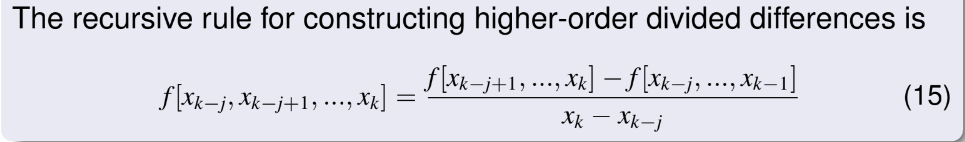 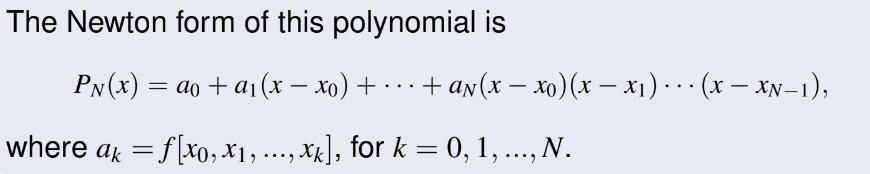

- The function arguments must be the set of points (X, Y) mentioned in the code box, finally evaluate the polynomial obtained at X=4.

x1 = [1,2,3,4,5,6];
y1 = [-3,0,15,48,105,192];


% Compute the Newton interpolating polynomial
P1 = my_NewtonPolynomial_juan_jaimes(x1, y1);

% Display the resulting polynomial
disp(P1);

$$\left(\left(X-2\right)\,\left(X+3\right)+3\right)\,\left(X-1\right)-3$$


% Evaluate the polynomial at a specific point (e.g., x = 2.5)
P1_value = double(subs(P1, 'X', 2.5));
disp(P1_value);

    5.6250



- **(0.5 points)** Using P(x) from the previous point, create a graph in the interval [0,3] and compare it with the graph of the function $\left(e^x \right)*0\ldotp 7$ in the same plot.

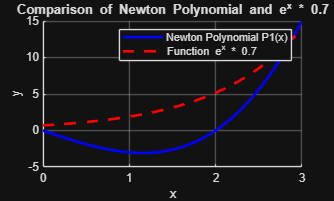

% Define the function e^x * 0.7
f = @(x) exp(x) * 0.7;

% Convert the symbolic Newton polynomial to a function handle
P1_func = matlabFunction(P1);

% Generate a vector of x values for the interval [0, 3]
x_values = linspace(0, 3, 100);  % 100 points between 0 and 3

% Evaluate the Newton polynomial and the function at each point
P1_values = P1_func(x_values);  % Evaluate Newton polynomial at each x
f_values = f(x_values);  % Evaluate the function e^x * 0.7 at each x

% Plot both functions
figure;
hold on;
plot(x_values, P1_values, 'b-', 'LineWidth', 2, 'DisplayName', 'Newton Polynomial P1(x)');
plot(x_values, f_values, 'r--', 'LineWidth', 2, 'DisplayName', 'Function e^x * 0.7');
hold off;

xlabel('x');
ylabel('y');
title('Comparison of Newton Polynomial and e^x * 0.7');
legend show;
grid on;

- **(2 points) **Use the created functions for Lagrange and Newton polynomial to find each interpolating polynomial based on $f\left(x\right)=3\sin^2 \left(\frac{\pi x}{6}\right)$with$x_0 =0,x_1 =1,x_2 =2,x_3 =3$and $x_4 =4\ldotp$

- In the same plot, compare Lagrange and Newton interpolating polynomials regarding to the real function $f\left(x\right)=3\sin^2 \left(\frac{\pi x}{6}\right)$. Also, illustrate the given points $\left(x_k ,y_k \right)$. 

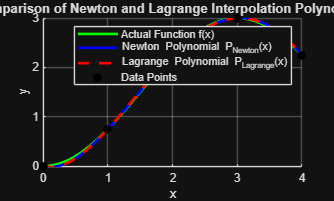

f = @(x) 3.*sin((pi.*x)/6).^2; 
x2 = [0,1,2,3,4];
y2 = [0,(3/4),(9/4),(3),(9/4)];
% Compute the Newton interpolating polynomial (symbolic expression)
Pnewton_symbolic = my_NewtonPolynomial_juan_jaimes(x2, y2);  % Returns symbolic expression for Newton polynomial
Pnewton_func = matlabFunction(Pnewton_symbolic);  % Convert symbolic expression to function handle

% Compute the Lagrange interpolating polynomial
Plagrange_func = my_LagrangePolynomial_juan_jaimes(x2, y2);


% Generate a vector of x values for the interval [0, 4]
x_values = linspace(0, 4, 100);  % 100 points between 0 and 4

% Evaluate the actual function, Newton polynomial, and Lagrange polynomial at each x value
f_values = f(x_values);  % Actual function values
Pnewton_values = Pnewton_func(x_values);  % Evaluate Newton polynomial
Plagrange_values = arrayfun(Plagrange_func, x_values);  % Evaluate Lagrange polynomial

% Plot the functions
figure;
hold on;

% Plot the actual function
plot(x_values, f_values, 'g-', 'LineWidth', 2, 'DisplayName', 'Actual Function f(x)');

% Plot the Newton interpolating polynomial
plot(x_values, Pnewton_values, 'b-', 'LineWidth', 2, 'DisplayName', 'Newton Polynomial P_{Newton}(x)');

% Plot the Lagrange interpolating polynomial
plot(x_values, Plagrange_values, 'r--', 'LineWidth', 2, 'DisplayName', 'Lagrange Polynomial P_{Lagrange}(x)');

% Mark the given data points on the plot
plot(x2, y2, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6, 'DisplayName', 'Data Points');

hold off;

% Add labels, title, and legend
xlabel('x');
ylabel('y');
title('Comparison of Newton and Lagrange Interpolation Polynomials');
legend show;
grid on;

### *Interpreting*

- **(1 points)** Determine the degree of the Taylor polynomial $P_N \left(x\right)$ expanded about $x_0 =\pi$ that should be used to approximate $\cos \left(\frac{33\pi }{32}\right)$ so that the error is less than ${10}^{-6}$. *Hint*. The error term $E_N \left(x\right)$ in Taylor polynomials is given by


$$E_N \left(x\right)=\frac{f^{\left(N+1\right)} \left(c\right)}{\left(N+1\right)!}{\left(X-X_0 \right)}^{\left(N+1\right)} ,$$


for some value $c=c\left(x\right)$ that lies netween $x$ and $x_0 \ldotp$

% Define the error bound
error_bound = 1e-6;

% Define the value of (x - x0) = (33*pi/32 - pi)
x_minus_x0 = pi / 32;

% Start checking for different values of N
N = 0;  % Start with degree 0

while true
    % Calculate the error term
    error_term = (factorial(N+1))^-1 * (x_minus_x0^(N+1));
    
    % Check if the error is within the desired bound
    if error_term <= error_bound
        break;
    end
    
    % Increment N to check the next degree
    N = N + 1;
end

% Display the result
disp(['The minimum degree of the Taylor polynomial is: ', num2str(N)]);

The minimum degree of the Taylor polynomial is: 4
